% This file is to aid the derivation of the case with damping, single ESS
% Can be generalized to multiple ESS
syms wlim H D C1 C2 C3 Pe Pess t tau

wlim = 1/60;

H = 26.3378;
D = 1;
Pe = 0.2;
Pess = 0.1;
tau = 1;

C1 = 0.0168; C2 = 0.0057; C3 = 0.0016;

w_exact_noPess(t) = C1/D*t - 1/D^2 *(2*H*C1 + D*(Pe + C2)) ...
    + 1/(2*D^2*H)*(4*H^2*C1 + 2*D*H*(Pe+C2) + C3*D^2)*exp(-D*t/(2*H))

$$w\_exact\_noPess(t) = 0.0168\,t+1.0907\,{\mathrm{e}}^{-0.0190\,t}-1.0907$$


w_exact(t) = C1/D*t - 1/D^2 *(2*H*C1 + D*(Pe + C2 - Pess)) ...
    + 1/(2*D^2*H)*(4*H^2*C1 + 2*D*H*(Pe+C2) + C3*D^2 - 4*H^2*D*Pess/(2*H-D*tau))*exp(-D*t/(2*H))...
    + Pess*tau/(2*H-D*tau)*exp(-t/tau)

$$w\_exact(t) = 0.0168\,t+0.0019\,{\mathrm{e}}^{-t}+0.9887\,{\mathrm{e}}^{-0.0190\,t}-0.9907$$

vpa(w_exact,3)

$$ans(t) = 0.0168\,t+0.0019\,{\mathrm{e}}^{-1\,t}+0.9887\,{\mathrm{e}}^{-0.0190\,t}-0.9907$$

tn_exact = double(solve(diff(w_exact,t)==0, t))

tn_exact = 5.8593

wtn_exact = double(subs(w_exact,t,tn_exact))

wtn_exact = -0.0075

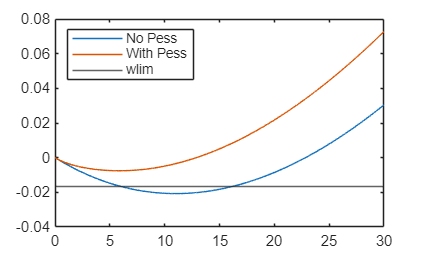


time = 0:0.01:30;
plot(time,double(w_exact_noPess(time)), time, double(w_exact(time)))
yline(-1/60)
legend("No Pess", "With Pess",'wlim','location','nw')

## Manually obtaining data points of Pe vs Pess for fixed wlim

% syms wlim H D C1 C2 C3 Pe Pess t tau
% 
% wlim = 1/60;
% 
% H = 26.3378;
% D = 1;
% Pe = 0;
% Pess = -0.1947;
% tau = 1;
% 
% C1 = 0.0168; C2 = 0.0057; C3 = 0.0016;
% 
% w_exact(t) = C1/D*t - 1/D^2 *(2*H*C1 + D*(Pe + C2 - Pess)) ...
%     + 1/(2*D^2*H)*(4*H^2*C1 + 2*D*H*(Pe+C2) + C3*D^2 - 4*H^2*D*Pess/(2*H-D*tau))*exp(-D*t/(2*H))...
%     + Pess*tau/(2*H-D*tau)*exp(-t/tau)
% 
% time = 0:0.01:30;
% nadir_exact = min(double(w_exact(time)))*60


## Testing the approximation

syms wlim H D C1 C2 C3 Pe Pess t tau
wlim = 1/60;

H = 26.3378;
D = 1;
% Pe = 0;
Pess = 0.1;
tau = 1;

C1 = 0.0168; C2 = 0.0057; C3 = 0.0016;
w_approx(t) = C1/D*t - 1/D^2 *(2*H*C1 + D*(Pe + C2 - Pess)) ...
    + 1/(2*D^2*H)*(4*H^2*C1 + 2*D*H*(Pe+C2) + C3*D^2 - 4*H^2*D*Pess/(2*H-D*tau))*exp(-D*t/(2*H))

$$w\_approx(t) = 0.0168\,t-\mathrm{Pe}+{\mathrm{e}}^{-0.0190\,t}\,\left(1.000\,\mathrm{Pe}+0.7887\right)-0.7907$$

wtn_approx = 2*H*C1/D^2 * log((4*H^2*C1 + 2*D*H*(Pe+C2) + C3*D^2 - 4*H^2*D*Pess/(2*H-D*tau))/(4*H^2*C1))-1/D*(Pe+C2-Pess)

$$wtn\_approx = 0.8850\,\log\left(1.1300\,\mathrm{Pe}+0.8913\right)-\mathrm{Pe}+0.0943$$


solve(wtn_approx == -wlim, Pe) % The results match the exact perfectly to at least 4 decimal points

$$ans = \left(\begin{array}{c} 0.2678+1.7489e-39\,\mathrm{i}\\ -0.0557+1.3704e-39\,\mathrm{i} \end{array}\right)$$


% Linear approx
    w = lambertw(-1,-exp(-1 - D^2*wlim/(2*H*C1) - C3*D^2/(4*H^2*C1)))

w = -1.2070

Pess = -0.18:0.01:0.6

Pess =    -0.1800   -0.1700   -0.1600   -0.1500   -0.1400   -0.1300   -0.1200   -0.1100   -0.1000   -0.0900   -0.0800   -0.0700   -0.0600   -0.0500   -0.0400   -0.0300   -0.0200   -0.0100         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100


    Pemax = -2*H*C1/D*(w+1+C3*D^2/(4*H^2*C1)+C2*D/(2*H*C1)) + Pess*(2*H/(2*H-D*tau) - D*tau/(2*H-D*tau) * (w/(1+w)))

Pemax =     0.0143    0.0234    0.0324    0.0415    0.0506    0.0596    0.0687    0.0778    0.0868    0.0959    0.1050    0.1140    0.1231    0.1322    0.1412    0.1503    0.1594    0.1684    0.1775    0.1865    0.1956    0.2047    0.2137    0.2228    0.2319    0.2409    0.2500    0.2591    0.2681    0.2772    0.2863    0.2953    0.3044    0.3135    0.3225    0.3316    0.3407    0.3497    0.3588    0.3679    0.3769    0.3860    0.3951    0.4041    0.4132    0.4222    0.4313    0.4404    0.4494    0.4585



    return

